# Using simulink to support the study of state space systems: Part 2

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of non-linear components and characteristics such as saturations, switches and non-simple shapes. In such cases non-linear models are needed and simulink is an ideal tool to capture this. 

The study of state space systems requires operations which are often most easily represented with block diagrams, that is simulink, rather than the precise algebra required in MATLAB m-files. This sequence of files demonstrates some simple simulink files for supporting such studies.

This file focuses on closed-loop behaviour with an observer for both the nominal and uncertain case. Logically this follows on from the introduction file on state space systems with simulink: ***state_space_and_simulinkfile1_control101.***

The simulink files were made with MATLAB 2023b so may not work with earlier versions of MATLAB.

### Similar files and the toolbox

See website below for more files like this.  

[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

### **Background on simulink**

The state space sequence does not focus on teaching simulink, but assumes familiarity and just uses the tool. Readers will be aware that there are number of settings in a simulink file, for example to define the format of input and output data. The settings and code snippets below work together, so if you change any of these settings then the code may need minor changes. A number of introductory files on simulink are available as listed next.

*myfirstsimulink_control101, intro_to_simulink_for_system_behaviour, car_suspension_simulink_control101, heating_system_simulink_control101, position_system_simulink_control101, hydraulic_system_simulink_control101, submersible_simulink_control101  *      

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction to the use of simulink with observers

- Simulation with initial state estimation error and zero target (nominal case)

- Simulation with non-zero zero target and disturbances (nominal case)

- Simulation with parameterisations errors, initial state estimation errors and disturbances.

## 1. Introduction to the use of simulink with observers

This file follows on from ***state_space_and_simulinkfile1_control101***, so it is assumed that readers are familiar with the content of that.

Here assume a state space model of the form:

$\dot{X} =A\;X+B\;U;\;Y=C\;X=d,\;$ (1.1)

with state *X*, input *U* and output *Y. * In place of the actual states  *X*, we will need to use estimates *Z* for those values, so for example the control law, with feedforward, takes the form: $U=-K\;Z+P\;r$, where $P=-\;{\left(C{\left\lbrack A-B\;K\right\rbrack }^{-1} B\right)}^{-1}$ is the feedforward term and the state feedback *K *is determined by some design method. For more on tracking see the file ***tracking_with_statespace_control101***.

- Define a model for the process: $\dot{Z} =A_m \;Z+B_m \;U;{\;\;\;\;Y}_m =C_m Z,\;$

- The model is run in parallel with the real process and the hope is that, given they have the same input, as long as $A_m \approx A,B_m \approx B,C_m \approx C$, then over time the model state *Z* will have the same value as the system state *X*.

A common solution is to modify the model/feedback equation to the following:


$$\dot{Z} =A_m \;Z+B_m \;U+L\left(Y-Y_m \right);{\;\;\;\;Y}_m =C_m Z,\;U=-K\;Z+P\;r,\;P=-\;{\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)}^{-1} \ldotp \;$$


That is,  measure the error between the model output and true process output and include this in the same manner as a feedback term.  In a slightly more compact form this observer/controller pair can be represented as:


$$\dot{Z} =\left\lbrack A_m -L{\;\mathrm{C}}_m \right\rbrack \;Z+{\left\lbrack \begin{array}{cc}
B_m  & L
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
U\\
Y
\end{array}\right\rbrack } ;{\;\;\;\;Y}_m =C_m Z,\;U=-K\;Z+P\;r\ldotp$$


For more on observers see the file ***observer_design_control101***.

This file uses simulink to code up all the models of this section into a simple block diagram. Readers will note (Figure 1) that there are in effect two separate feedback loops (one for observer, one for state feedback) and several of the blocks are simply to export the simulation data with a clear naming convention to the workspace.

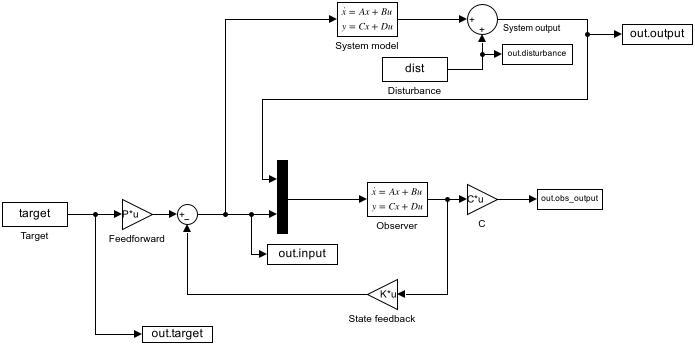

**Figure 1:** Simulink diagram for ***state_space_simulinkfile_observer_control101.slx***

***Remarks ***

- For the regulation case simply set the target input signal to zero. The code and simulink file currently assume a zero initial condition for the states; again this is straightforward to change.

- Where included, this file includes only output disturbances *d*, so the output model is modified to: $Y=C\;X+d$

- In the case of parameter uncertainty then: $A_m \not= A,B_m \not= B,C_m \not= C$.

### 1.2 Content of this file

This file focuses on the uncertain case so explores how well the observer behaves when there are parameterisation errors and disturbances and thus gradually increases the complexity and reality.

- Simulation for nominal case with initial state estimation error and zero target.

- Simulation for nominal case but with a target change and disturbances.

- Simulation with parameterisation errors, initial state estimation errors and disturbances.

It will be clear in the final section that, albeit the observer is working to some extent, especially in the nominal case, it cannot deal with uncertainty and thus further improvements will be needed which are covered in: ***state_space_and_simulinkfile3_control101***

**Remark:** Readers will be aware that there are number of settings in a simulink file, for example to define the format of input and output data. The settings and code snippets below work together, so if you change any of these settings then the code may need minor changes.

## 2. Simulation with initial state estimation error and zero target (nominal case)

The code below lays out the data required for the simulink file, collects the output and creates some plots. Clearly this can be modified as required by readers.

**Remark**: The plots below do not include plots of the observer output, states or inputs, but the data is collected and clearly defined below so it will easy for the reader to add such plots as they require.

disp('Section 2: Regulation responses in the nominal case')

Section 2: Regulation responses in the nominal case


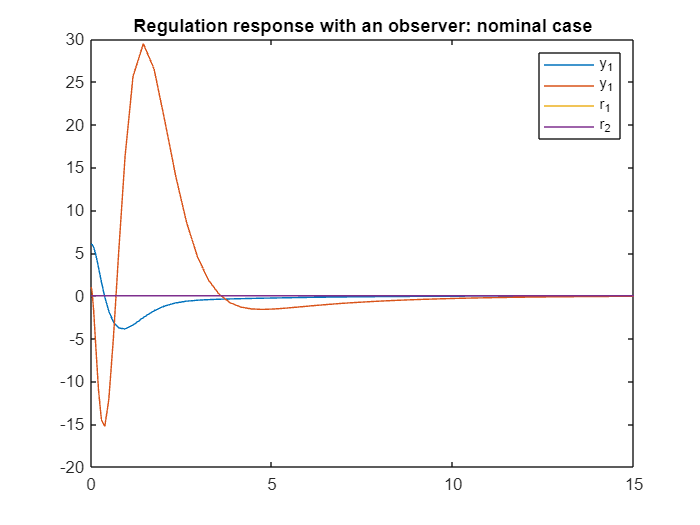

% Real process model
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D=zeros(2,2);
x0=[1;1;1;1];

% model - values used in observer and controller design
Am=A;Bm=B;Cm=C;Dm=D;

% Control design
Q = [C'*C]; 
R=eye(2);
K=lqr(A,B,Q,R);
P = -inv(Cm*inv(Am-Bm*K)*Bm);

% Observer implementation 
deseig_ob = [-2+0.4i,-2-0.4i,-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(4); Dob = zeros(4,4);

% input signal characterisation
endtime=15;
dist.time = linspace(0,endtime,200);
dist.signals.values = 0* [[zeros(120,1);ones(80,1)*0.2],[zeros(140,1);ones(60,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values = 0* [[zeros(10,1);ones(190,1)*1],[zeros(40,1);ones(160,1)*0.6]];
target.signals.dimensions = 2;

% simulation
Data= sim('state_space_simulink_observer_control101.slx');
y=Data.output.signals;          % system output
d=Data.disturbance.signals;     % disturbance signal
r=Data.target.signals;          % target
y_o = Data.obs_output.signals; % observer output
u = Data.input.signals;        % input

% Plotting
plot(Data.tout,y.values,Data.tout,r.values)
legend('y_1','y_1','r_1','r_2')
title('Regulation response with an observer: nominal case')


%print(['-sstate_space_simulink_observer_control101'],'-djpeg',['state_space_simulink_observer_control101.jpg'])

## 3. Simulation with non-zero zero target and disturbances (nominal case)

This section introduces some uncertainty and specifically the output disturbance but with no parameterisation errors. The code below lays out the data required for the simulink file, collects the output and creates some plots. Clearly this can be modified as required by readers.

The figures show that while the disturbance is zero, the tracking is good as expected for the nominal case. However, although the disturbance can be rejected to some extent, because of the lack of integral action, even with a perfect model offset will result when disturbances are non-zero.

disp('Section 3: Observer and disturbances in nominal case')

Section 3: Observer and disturbances in nominal case


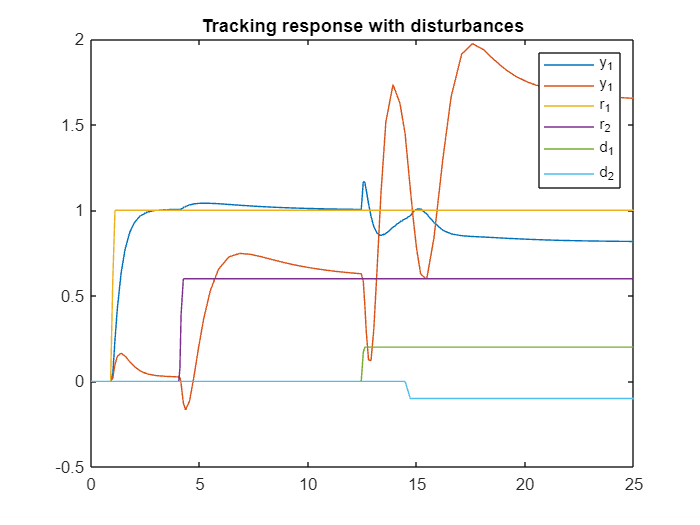


% Real process model
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D=zeros(2,2);
x0=[1;1;1;1];

% model - values used in observer and controller design
Am=A;Bm=B;Cm=C;Dm=D;

% Control design
Q = [C'*C]; 
R=eye(2);
K=lqr(A,B,Q,R);
P = -inv(Cm*inv(Am-Bm*K)*Bm);

% Observer implementation 
deseig_ob = [-2+0.4i,-2-0.4i,-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(4); Dob = zeros(4,4);dist.signals.values =  [[zeros(120,1);ones(80,1)*0.2],[zeros(140,1);ones(60,1)*(-0.1)]];

% input signal characterisation
endtime=25;
dist.time = linspace(0,endtime,240);
dist.signals.values =  [[zeros(120,1);ones(120,1)*0.2],[zeros(140,1);ones(100,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values =  [[zeros(10,1);ones(230,1)*1],[zeros(40,1);ones(200,1)*0.6]];
target.signals.dimensions = 2;
x0=x0*0;

% Simulation
Data= sim('state_space_simulink_observer_control101.slx');
y=Data.output.signals;
d=Data.disturbance.signals;
r=Data.target.signals;
y_o = Data.obs_output.signals;
u = Data.input.signals;

% Plotting
plot(Data.tout,y.values,Data.tout,r.values,Data.tout,d.values)
legend('y_1','y_2','r_1','r_2','d_1','d_2')
title('Tracking response with disturbances')

## 4. Simulation with parameterisations errors, initial state estimation errors and disturbances

This section now introduces more of the expected uncertainty in a real process, namely the model parameters themselves will always be estimates. Three cases will be illustrated separately to improve clarity:

- Tracking errors

- Disturbance rejection.

- State estimation errors and regulation

It will be clear that there is offset in the steady-state and thus we need further improvements in the feedback design. This si covered in the next file: ***state_space_and_simulinkfile2_control101***

disp('Section 4: Responses with parameter uncertainty')

Section 4: Responses with parameter uncertainty


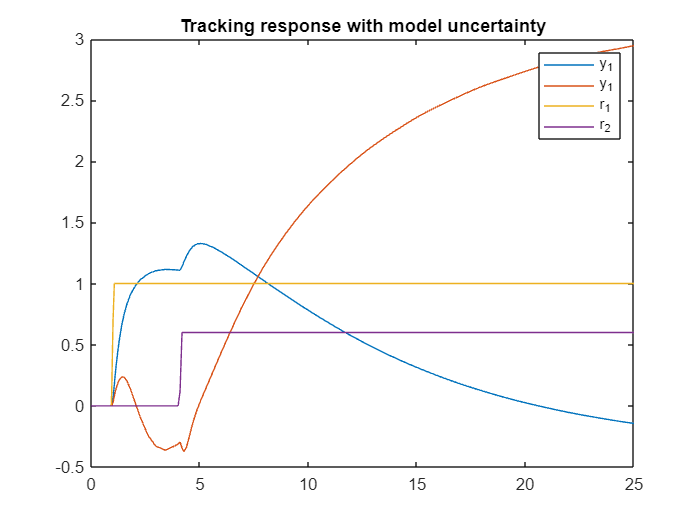


% Real process model
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D=zeros(2,2);
x0=[1;1;1;1];

% model - values used in observer and controller design
Am=[-0. -0.4 -0.6 0.21;0.4 1 .7 .5;-0.3 1.0 1 0;0.8 1.1 -0.3 0]; 
Bm=[1 0;-1 1;0 0.3;-1 1.9];
Cm=[3.2 2 1.1 0;0 0 0 1];
Dm = zeros(2,2);

% Control design
Q = [C'*C]; 
R=eye(2);
K=lqr(A,B,Q,R);
P = -inv(Cm*inv(Am-Bm*K)*Bm);

% Observer implementation 
deseig_ob = [-2+0.4i,-2-0.4i,-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(4); Dob = zeros(4,4);dist.signals.values =  [[zeros(120,1);ones(80,1)*0.2],[zeros(140,1);ones(60,1)*(-0.1)]];

% input signal characterisation
endtime=25;
dist.time = linspace(0,endtime,240);
dist.signals.values =  0*[[zeros(20,1);ones(220,1)*0.2],[zeros(100,1);ones(140,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values =  0*[[zeros(10,1);ones(230,1)*1],[zeros(40,1);ones(200,1)*0.6]];
target.signals.dimensions = 2;

% State estimation errors
Data3= sim('state_space_simulink_observer_control101.slx');
% tracking errors
x0=x0*0;
target.signals.values =  [[zeros(10,1);ones(230,1)*1],[zeros(40,1);ones(200,1)*0.6]];
Data1= sim('state_space_simulink_observer_control101.slx');
% Disturbance rejection
target.signals.values = 0*[[zeros(10,1);ones(230,1)*1],[zeros(40,1);ones(200,1)*0.6]];
dist.signals.values =  [[zeros(20,1);ones(220,1)*0.2],[zeros(100,1);ones(140,1)*(-0.1)]];
Data2= sim('state_space_simulink_observer_control101.slx');

% Plotting for tracking example
y=Data1.output.signals;
r=Data1.target.signals;
plot(Data1.tout,y.values,Data1.tout,r.values)
legend('y_1','y_1','r_1','r_2')
title('Tracking response with model uncertainty')

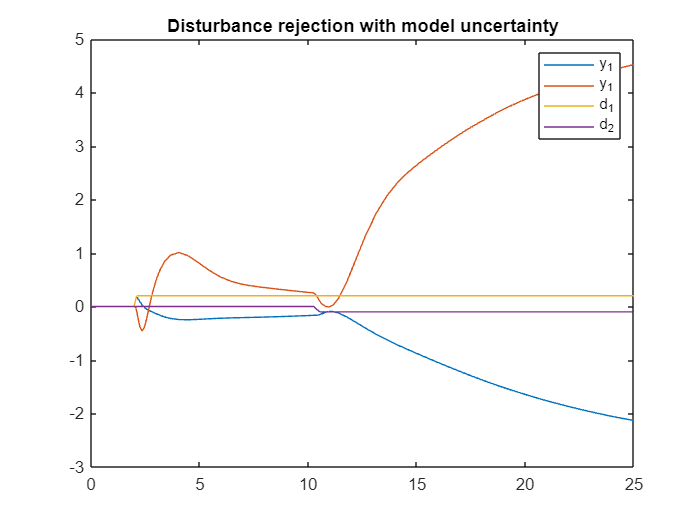


% Plotting for disturbance rejection example
y=Data2.output.signals;
d=Data2.disturbance.signals;
plot(Data2.tout,y.values,Data2.tout,d.values)
legend('y_1','y_2','d_1','d_2')
title('Disturbance rejection with model uncertainty')

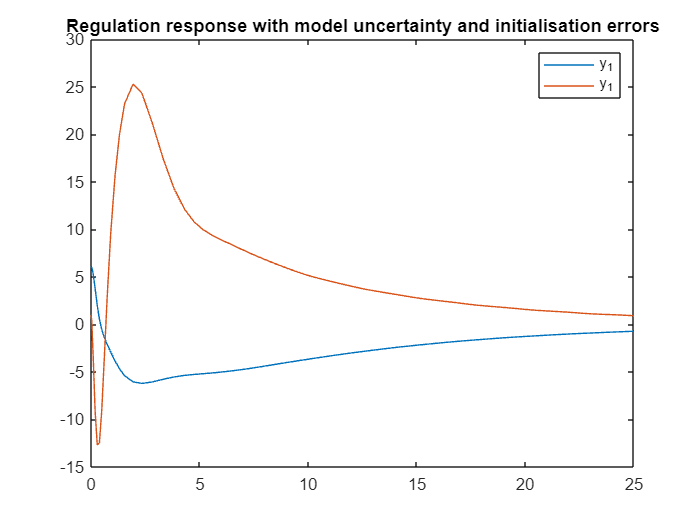


% Plotting for initialisation errors
y=Data3.output.signals;
plot(Data3.tout,y.values)
legend('y_1','y_2')
title('Regulation response with model uncertainty and initialisation errors')